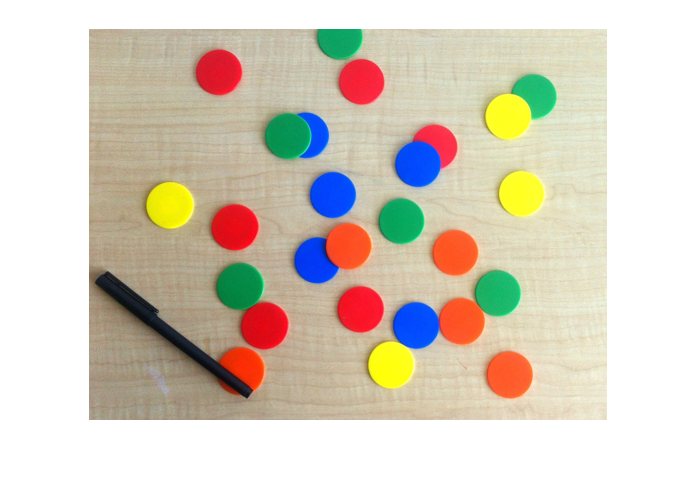

img = imread("coloredchips.png");
imshow(img)

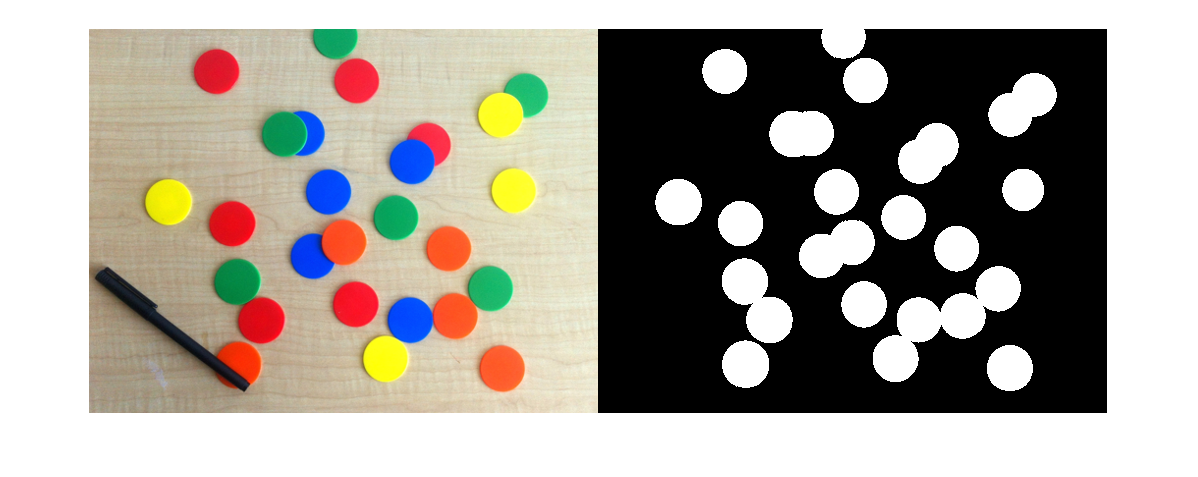

BWdark = segmentImageDark(img);
BWbright = segmentImageBright(img);
BW = BWdark | BWbright;
montage({img,BW})

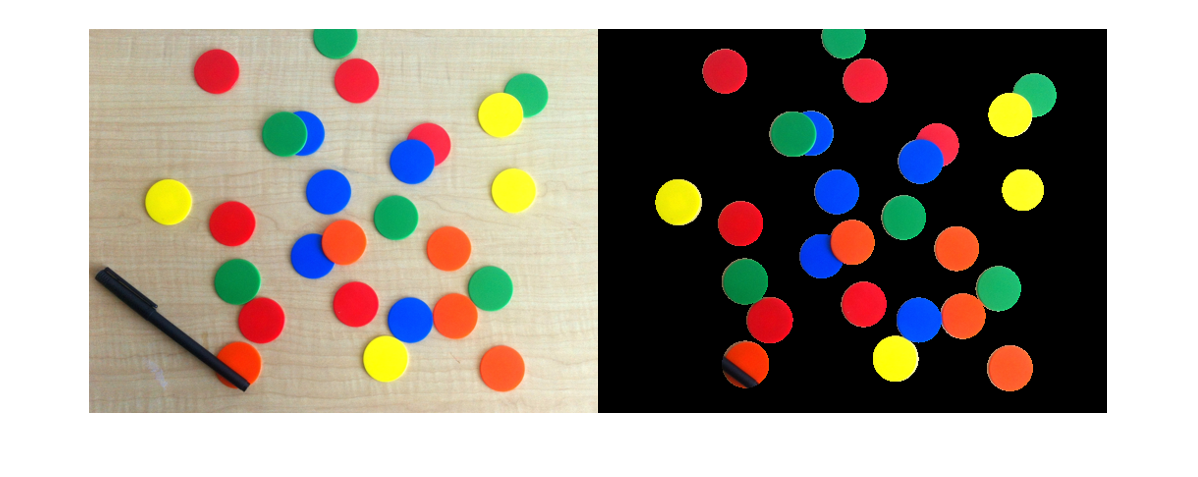

maskedImg = img;
maskedImg(repmat(~BW,1,1,3)) = 0;
montage({img,maskedImg})